%% --------------------------------------------------------------
%  STEP 8 – Hydrodynamic forces with Morison equation
%           (wave + current, with varying diameter)
% --------------------------------------------------------------

% --- Hydrodynamic parameters (edit as needed) ---
rho = 1025;     % water density (kg/m^3)
CM  = 2.0;      % inertia coefficient  (typical order)
CD  = 0.7;      % drag coefficient     (typical order)

% --- Structural geometry ---
D_base   = 20;       % [m] base diameter at seabed (your unknown D – set value)
D_shaft  = 15;       % [m] shaft diameter
H_struct = h_water;  % [m] seabed to CD (H in sketch)
h_plinth = 5;        % [m] height of constant-D base block
theta_cone = 60;     % [deg] cone angle to horizontal

z_seabed     = -H_struct;                     % seabed level in CD coordinates
z_plinth_top = z_seabed + h_plinth;           % top of plinth (start of cone)

% vertical height of cone from geometry
h_cone = ((D_base - D_shaft)/2) * tand(theta_cone);

z_shaft_base = z_plinth_top + h_cone;         % level where diameter becomes 15 m

% --- Build diameter profile D(z) along the wave grid (z_CD_wave) ---
D_profile = zeros(size(z_CD_wave));

for i = 1:length(z_CD_wave)
    z = z_CD_wave(i);

    if z <= z_plinth_top
        % region of constant base diameter
        D_profile(i) = D_base;

    elseif z <= z_shaft_base
        % conical transition: linear interpolation from D_base to D_shaft
        z_rel = z - z_plinth_top;  % vertical distance measured from top of plinth
        D_profile(i) = D_base - (D_base - D_shaft) * (z_rel / h_cone);

    else
        % vertical shaft of constant diameter 15 m
        D_profile(i) = D_shaft;
    end
end

%% --- Morison equation components (per unit length) ---

% Relative horizontal velocity = (wave orbital + mean current)
u_rel = u_wave + Total_current;         % [m/s], same vertical grid as z_CD_wave

% Inertia term (uses acceleration a_wave)
F_I = rho * (pi/4) * CM .* (D_profile.^2) .* a_wave;              % [N/m]

% Drag term (uses relative velocity)
F_D = 0.5 * rho * CD .* D_profile .* u_rel .* abs(u_rel);         % [N/m]

% Total horizontal force per unit length
Fz_total = F_I + F_D;                                             % [N/m]

%% --- Resultant force and overturning moment ---

% Net horizontal force (integrated from seabed to still water level)
F_total = trapz(z_CD_wave, Fz_total);          % [N]

% Moments about seabed (z = z_seabed) and about CD (z = 0)
lever_seabed = z_CD_wave - z_seabed;           % [m]
lever_CD      = z_CD_wave;                     % [m]

M_seabed = trapz(z_CD_wave, Fz_total .* lever_seabed);   % [N·m]
M_CD     = trapz(z_CD_wave, Fz_total .* lever_CD);       % [N·m]

fprintf('Resultant horizontal Morison force (seabed–SWL): %.1f kN\n', F_total/1e3);

Resultant horizontal Morison force (seabed–SWL): 10247.6 kN


fprintf('Overturning moment about seabed:                 %.1f MN·m\n', M_seabed/1e6);

Overturning moment about seabed:                 315.3 MN·m


fprintf('Overturning moment about Chart Datum (z=0):      %.1f MN·m\n', M_CD/1e6);

Overturning moment about Chart Datum (z=0):      -94.6 MN·m


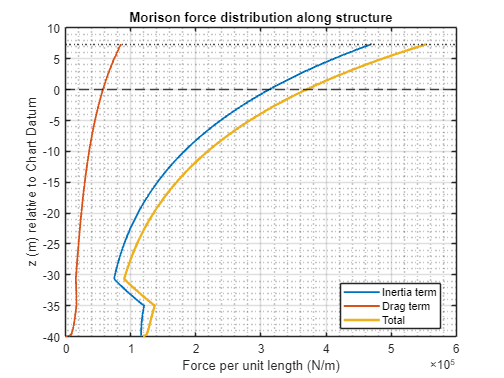


%% --- Plot force distribution vs depth (optional) ---
figure;
plot(F_I, z_CD_wave, 'LineWidth', 1.5); hold on;
plot(F_D, z_CD_wave, 'LineWidth', 1.5);
plot(Fz_total, z_CD_wave, 'LineWidth', 2);
yline(0,'k--');      % CD
yline(eta,'k:');     % still water level
xlabel('Force per unit length (N/m)');
ylabel('z (m) relative to Chart Datum');
title('Morison force distribution along structure');
legend('Inertia term','Drag term','Total','Location','best');
grid on; grid minor;














%% --------------------------------------------------------------
%  STEP 9 – Resultant force & moment for discrete phases (every 30°)
% --------------------------------------------------------------

% We use linear wave theory:
% u(z,phi) = u_wave(z) * cos(phi)
% a(z,phi) = -a_wave(z) * sin(phi)
% where u_wave and a_wave are the amplitudes you already computed.

phases_deg = 0:30:330;               % 0, 30, ..., 330 degrees
phases_rad = deg2rad(phases_deg);
Nphi       = numel(phases_rad);

F_total_phase   = zeros(1, Nphi);    % resultant horizontal force [N]
M_seabed_phase  = zeros(1, Nphi);    % overturning moment about seabed [N·m]
M_CD_phase      = zeros(1, Nphi);    % moment about Chart Datum z=0 [N·m]

lever_seabed = z_CD_wave - z_seabed; % lever arm to seabed
lever_CD     = z_CD_wave;            % lever arm to CD

for iphi = 1:Nphi
    phi = phases_rad(iphi);

    % wave orbital velocity & acceleration at this phase
    u_wave_phi =  u_wave .* cos(phi);
    a_wave_phi = -a_wave .* sin(phi);  % sign consistent with du/dt

    % add steady current (wind + tide)
    u_rel = u_wave_phi + Total_current;

    % Morison terms per unit length
    F_I = rho * (pi/4) * CM .* (D_profile.^2) .* a_wave_phi;           % inertia
    F_D = 0.5 * rho * CD .* D_profile .* u_rel .* abs(u_rel);          % drag
    Fz  = F_I + F_D;                                                   % total

    % Integrate over depth
    F_total_phase(iphi)  = trapz(z_CD_wave, Fz);                       % [N]
    M_seabed_phase(iphi) = trapz(z_CD_wave, Fz .* lever_seabed);       % [N·m]
    M_CD_phase(iphi)     = trapz(z_CD_wave, Fz .* lever_CD);           % [N·m]
end

% Print a small table (force in kN, moment in MNm)
fprintf('\nPhase (deg)   F_total (kN)   M_seabed (MN·m)   M_CD (MN·m)\n');


Phase (deg)   F_total (kN)   M_seabed (MN·m)   M_CD (MN·m)


for iphi = 1:Nphi
    fprintf('%4.0f         %10.2f      %10.3f        %10.3f\n', ...
        phases_deg(iphi), ...
        F_total_phase(iphi)/1e3, ...
        M_seabed_phase(iphi)/1e6, ...
        M_CD_phase(iphi)/1e6);
end

   0            1608.53          50.056           -14.286
  30           -2835.91         -86.909            26.527
  60           -6311.07        -194.788            57.655
  90           -7829.38        -242.549            70.626
 120           -6955.80        -216.333            61.899
 150           -3952.65        -124.227            33.879
 180             319.02           6.965            -5.796
 210            4686.42         141.028           -46.429
 240            8007.50         243.103           -77.198
 270            9448.76         287.962           -89.989
 300            8652.24         264.648           -81.441
 330            5803.16         178.346           -53.780


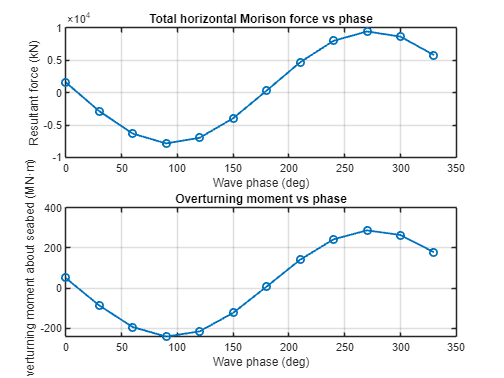


% Optional plots
figure;
subplot(2,1,1);
plot(phases_deg, F_total_phase/1e3, '-o', 'LineWidth', 1.5);
xlabel('Wave phase (deg)');
ylabel('Resultant force (kN)');
title('Total horizontal Morison force vs phase');
grid on;

subplot(2,1,2);
plot(phases_deg, M_seabed_phase/1e6, '-o', 'LineWidth', 1.5);
xlabel('Wave phase (deg)');
ylabel('Overturning moment about seabed (MN·m)');
title('Overturning moment vs phase');
grid on;

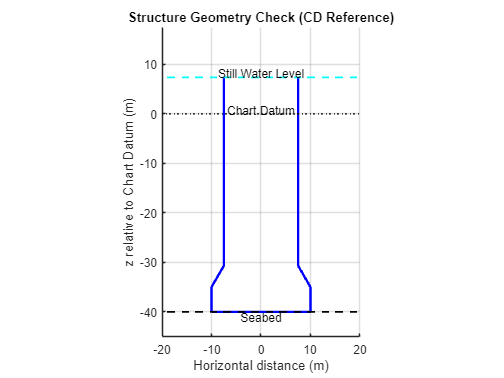










%% --------------------------------------------------------------
%  SIMPLE STRUCTURE GEOMETRY PLOT (CD reference)
% --------------------------------------------------------------

figure; hold on; grid on;

% Key vertical levels
z_seabed     = -h_water;
z_plinth_top = z_seabed + h_plinth;

% Cone height
h_cone = ((D_base - D_shaft)/2) * tand(theta_cone);
z_shaft_base = z_plinth_top + h_cone;

% --- Build vertical coordinates ---
z_geom = [ ...
    z_seabed      % seabed
    z_plinth_top  % top of plinth
    z_shaft_base  % end of cone start of shaft
    eta           % still water level
];

% --- Corresponding HALF widths (radius = D/2) ---
r_geom = [ ...
    D_base/2
    D_base/2
    D_shaft/2
    D_shaft/2
];

% --- Build left and right outlines ---
z_outline = [z_seabed; z_plinth_top; z_shaft_base; eta];

% left side (negative x)
x_left  = -r_geom;
% right side (positive x)
x_right = +r_geom;

% --- Draw structure outline ---
plot(x_left,  z_geom, 'b-', 'LineWidth', 2);
plot(x_right, z_geom, 'b-', 'LineWidth', 2);

% close bottom at seabed
plot([x_left(1) x_right(1)], [z_seabed z_seabed], 'b-', 'LineWidth', 2);

% draw seabed
plot([-50 50], [z_seabed z_seabed], 'k--', 'LineWidth', 1.5);
text(0, z_seabed-1, 'Seabed','HorizontalAlignment','center');

% draw still water level
plot([-50 50], [eta eta], 'c--', 'LineWidth', 1.5);
text(0, eta+0.8, 'Still Water Level','HorizontalAlignment','center');

% CD line
plot([-50 50], [0 0], 'k:', 'LineWidth', 1);
text(0, 0.8, 'Chart Datum','HorizontalAlignment','center');

ylabel('z relative to Chart Datum (m)');
xlabel('Horizontal distance (m)');
title('Structure Geometry Check (CD Reference)');

axis equal
ylim([z_seabed-5, eta+10]);
xlim([-max(D_base) max(D_base)]);
set(gca,'YDir','normal');


%% --------------------------------------------------------------
%  STEP 10 – Extract maximum total force and moment over all phases
% --------------------------------------------------------------

% Use absolute values (worst-case magnitude)
[ F_max_abs, idx_Fmax ]   = max(abs(F_total_phase));
[ M_max_abs, idx_Mmax ]   = max(abs(M_seabed_phase));
[ MCD_max_abs, idx_MCDmax ] = max(abs(M_CD_phase));

phase_Fmax   = phases_deg(idx_Fmax);
phase_Mmax   = phases_deg(idx_Mmax);
phase_MCDmax = phases_deg(idx_MCDmax);

fprintf('\n=== PEAK VALUES OVER ALL PHASES (30° steps) ===\n');


=== PEAK VALUES OVER ALL PHASES (30° steps) ===


fprintf('Max |F_total|       = %.2f kN   at phase = %3.0f°\n', F_max_abs/1e3,  phase_Fmax);

Max |F_total|       = 9448.76 kN   at phase = 270°


fprintf('Max |M_seabed|      = %.3f MN·m at phase = %3.0f°\n', M_max_abs/1e6,  phase_Mmax);

Max |M_seabed|      = 287.962 MN·m at phase = 270°


fprintf('Max |M_CD|          = %.3f MN·m at phase = %3.0f°\n\n', MCD_max_abs/1e6, phase_MCDmax);

Max |M_CD|          = 89.989 MN·m at phase = 270°

